% ----------------------------------------------
% This program formulates the minimimal variance mechanism problem into a
% linear programing problem, and solves it using the built-in solver in Matlab.
% Comments are adquent in the code. 
% If you have any question,
% please feel free to contact Fei Wei at feiwei@nus.edu.sg
% ----------------------------------------------

close all
clear
% Please be advised this section is another experiment.
q = 10; % quantization level
% eps = 2; % privacy parameter
delta = 0; % privacy parameter
r=0.5; % geometric series constant
axRatio = 2; %the ratio amax/xmax
eps = 2; % the privacy parameter

filename = sprintf("estimated_freq_2_GAUSSIAN_100000_-5_5_1_0.1_0.25.csv");
x_P = readmatrix(filename);
x_P = x_P'./ sum(x_P);

xmax = 1;
xmin = -xmax;
M = length(x_P); % Total number of bins in [-xmax,xmax]
x_bin_size = (xmax-xmin)/M;
x_grid = linspace(xmin+0.5*x_bin_size,xmax-0.5*x_bin_size,M);

% x_P = ones(1,M)/M; % Uniform distribution for testing

[varVector,pMatrix,a_grid] =...
    opt_variance(eps,delta,r,axRatio,x_grid,x_P);

--------------------------------
eps = 2.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.5499   -0.0517    0.0351   -0.1832    0.0508    0.0197   -0.3303   -0.0226   -0.0897   -0.0963    0.0350    0.0607    0.2437   -0.0039    0.3521   -0.0019    0.1918   -0.0590   -0.0324    0.0790


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.8794    0.8394    0.8162    0.7845    0.7530    0.7216    0.6716    0.6116    0.5316    0.4584    0.4858    0.5458    0.6158    0.6858    0.7658    1.4933    0.8658    0.8858    0.8928    0.9084


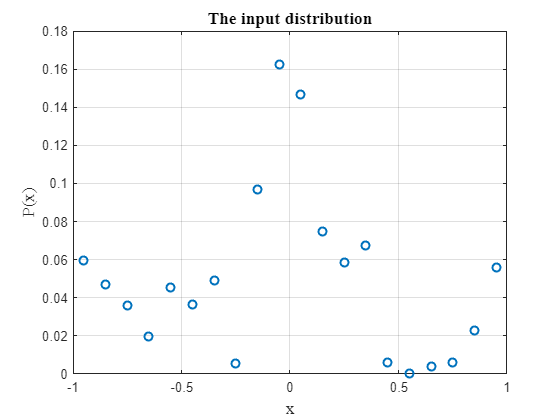

filename = sprintf('uniform_axRatio%d_xmax%.1f_eps%.1f_delta%.1f_pMatrix.csv', axRatio,xmax,eps,delta);
writematrix(pMatrix,filename,'Delimiter','comma');
% filename = sprintf('uniform_axRatio%d_xmax%.1f_eps%.1f_delta%.1f_xGrid.csv', axRatio,xmax,eps,delta);
% writematrix(x_grid,filename,'Delimiter','comma');
% filename = sprintf('uniform_axRatio%d_xmax%.1f_eps%.1f_delta%.1f_aGrid.csv', axRatio,xmax,eps,delta);
% writematrix(a_grid,filename,'Delimiter','comma');
% The plots

figure;
plot(x_grid,x_P,'o',LineWidth=1.5);
title("The input distribution",'FontSize',13,'FontName','Times');
xlabel("x",'FontSize',13,'FontName','Times');
ylabel("P(x)",'FontSize',13,'FontName','Times');
grid on

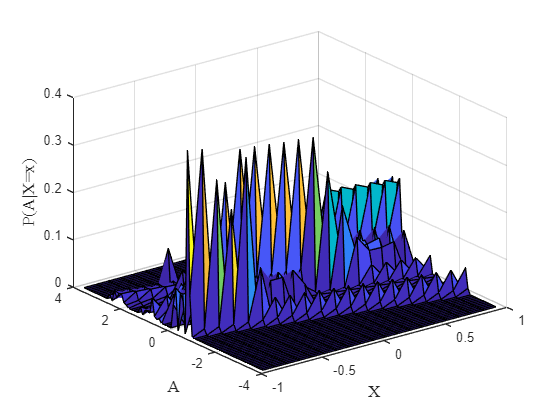

figure
[X_grid,Y_grid] = meshgrid(-x_grid,a_grid);
surf(X_grid,Y_grid,pMatrix');
xlabel("X",'FontSize',13,'FontName','Times');
ylabel("A",'FontSize',13,'FontName','Times');
zlabel("P(A|X=x)",'FontSize',13,'FontName','Times');